%正面同定実験の処理用スクリプト
clear, clc, close all
list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2);% インポート用のセル
% MusicTime PlayerRotY (deg) Target (deg) Accuracy (deg)  SpentTime MusicVol VibVol

for i = 1:numFiles
% for i = 1:1
    %     Mx{i,1} = readmatrix(list(i).name);
    Mx{i,1} = readtable(list(i).name,'PreserveVariableNames',true);
    Mx{i,2} = rmmissing(Mx{i,1}); % 回答行だけ抽出（文字列が入った行を無視）
    Mx{i,3} = mean(Mx{i,2}{:,4}); % dotMean
    Mx{i,4} = rad2deg(acos(Mx{i,3})); %dotから角度に変換
    Mx{i,5} = rad2deg( std(Mx{i,2}{:,4})); % radStd
    Mx{i,6} = mean(Mx{i,2}{:,5}); % timeMean
    Mx{i,7} = std(Mx{i,2}{:,5}); % timeStd
    Mx{i,8} = Mx{i,2}{1,10}; % musicId
    Mx{i,9} = i; % musicId
end

% 行末に説明を追加
Mx{i+1,1} = '生データ';
Mx{i+1,2} = '回答抽出';
Mx{i+1,3} = 'dotMean';
Mx{i+1,4} = 'degMean';
Mx{i+1,5} = 'degStd';
Mx{i+1,6} = 'timeMean';
Mx{i+1,7} = 'timeStd';
Mx{i+1,8} = 'musicId';
Mx{i+1,9} = 'subjId';



保存先:C:\Dropbox\論文\2稿目_音楽振動ナビ\V2実験データ\exp2_FrontDetect\matlab.mat



SortCell = Mx;
SortCell(i+1,:) = [];
Mz = sortrows(SortCell,8);

save;

## 箱ひげ図描画

% [Mx{1,2}{:,4}];
accuracy = 0;
accuracy_A = 0;
accuracy_B = 0;
time = 0;
time_A = 0;
time_B = 0;
grp = 0;
grp_A = 0;
grp_B = 0;

% for i = 1:size(Mx,1)-2
% 音楽順に並び替えたいとき
Data = Mz; 
for i = 1:size(Data,1)
    accuracy = horzcat(accuracy, transpose([Data{i,2}{:,4}]));
    time = horzcat(time, transpose([Data{i,2}{:,5}]));
    grp = horzcat(grp, i*ones(1,size(Data{i,2},1)));
    % music の種類で場合分け
    if Data{i,8} == 1
        accuracy_A  = horzcat(accuracy_A, transpose([Data{i,2}{:,4}]));
        time_A = horzcat(time_A, transpose([Data{i,2}{:,5}]));
        grp_A = horzcat(grp_A, i*ones(1,size(Data{i,2},1)));
    elseif Data{i,8} == 2
        accuracy_B  = horzcat(accuracy_B, transpose([Data{i,2}{:,4}]));
        time_B = horzcat(time_B, transpose([Data{i,2}{:,5}]));
        grp_B = horzcat(grp_B, i*ones(1,size(Data{i,2},1)));
    end
end
accuracy(:,1) = []; accuracy_A(:,1)=[]; accuracy_B(:,1)=[];
time(:,1) =[]; time_A(:,1) =[]; time_B(:,1) =[];
grp(:,1) =[]; grp_A(:,1) =[]; grp_B(:,1) =[];
accuracy = rad2deg(acos(accuracy));
accuracy_A = rad2deg(acos(accuracy_A));
accuracy_B = rad2deg(acos(accuracy_B));

% % 30°以下での正答率
% t = sum(accuracy(1,:)<=30);
% b = size(accuracy,2)-2;
% t/b
% % 全試行平均
% tmp = accuracy;
% tmp(:,find(tmp>90))=[]
% mean(tmp)

% 参加者間でanova。P<0.05なら違いがある、すなわち全試行NG
% [p,tbl,stats] = anova1(accuracy,grp)
% [p,tbl,stats] = anova1(time,grp)

figure;
boxplot(accuracy,grp);
hold on
swarmchart(grp,accuracy,[],'blue','filled','SizeData',10);
ylabel('accuracy (deg)')
xlabel('participant No.')
title('total')
hold off

figure;
boxplot(time,grp);
hold on
swarmchart(grp,time,[],'blue','filled','SizeData',10);
ylabel('time (s)')
xlabel('participant No.')
title('total')
hold off
save;


## 平均の計算

% 外れ値の除外
Mam = Mz;
Mam{6,2}(20:21,:)=[];
Mam{21,2}(2,:)=[];
for i = 1:numFiles
    Mam{i,3} = mean(Mam{i,2}{:,4}); % dotMean
    Mam{i,4} = rad2deg(acos(Mam{i,3})); %dotから角度に変換
    Mam{i,5} = rad2deg( std(Mam{i,2}{:,4})); % radStd
    Mam{i,6} = mean(Mam{i,2}{:,5}); % timeMean
    Mam{i,7} = std(Mam{i,2}{:,5}); % timeStd
end

accu_total = mean([Mam{:,4}])

accu_total = 19.6611

std_total = std([Mam{:,4}])

std_total = 6.1897

accu_A = mean([Mam{1:12,4}])

accu_A = 22.2060

std_A = std([Mam{1:12,4}])

std_A = 6.4811

accu_B = mean([Mam{13:24,4}])

accu_B = 17.1162

std_B = std([Mam{13:24,4}])

std_B = 4.8962


[p,h,stats] = ranksum([Mam{1:12,4}],[Mam{13:24,4}])

p = 0.0464

h = logical
   1


stats = フィールドをもつ struct :
       zval: 1.9919
    ranksum: 185




time_total = mean([Mam{:,6}])

time_total = 21.1347

std_total = std([Mam{:,6}])

std_total = 8.3241


time_A = mean([Mam{1:12,6}])

time_A = 21.9796

std_A = std([Mam{1:12,6}])

std_A = 10.1544

time_B = mean([Mam{13:24,6}])

time_B = 20.2897

std_B = std([Mam{13:24,6}])

std_B = 6.3412

[p,h,stats] = ranksum([Mam{1:12,6}],[Mam{13:24,6}])

p = 0.7950

h = logical
   0


stats = フィールドをもつ struct :
       zval: 0.2598
    ranksum: 155


save;


保存先:C:\Dropbox\論文\2稿目_音楽振動ナビ\V2実験データ\exp2_FrontDetect\matlab.mat



## exp2 グラフ清書

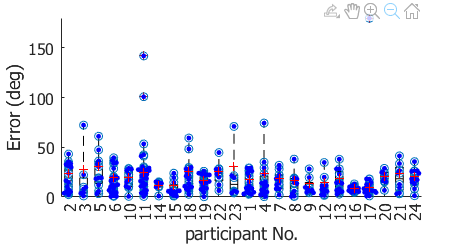


close all;
figure('Position',[0 -700 840 440]);
mzAId = [2 3 5 6 10 11 14 15 18 19 22 23];
mzBId = [1 4 7 8 9 12 13 16 17 20 21 24];
boxplot(accuracy,grp,'Whisker',4.1,'Colors','k');

hold on

% repmat([0 0 1],[8,1])

% beeswarm を使うため、24*8 を1列に変形する
dotSize = .4;
y = accuracy.';
x = grp.';
cmap = repmat([0 0 1],[24,1]);
%  repmat([0 0 1],[8,1])
beeswarm(x,y,'dot_size', dotSize,'colormap',cmap,...
'MarkerFaceAlpha',1,'MarkerEdgeColor','none',...
'corral_style','random'); 
% swarmchart(xl,data,[],...

% swarmchart(grp,accuracy,[],'blue','filled','SizeData',10);


plot([Mam{:,4}],'+r');

ylabel('Error (deg)')
xlabel('participant No.')
% title('total')

xticklabels([mzAId mzBId])
ax = gca; % current axes
ax.FontSize = 12;
ax.FontName = 'tahoma';
ylim([0,180])
% yticks(:4)
box off
hold off

## 30°未満の正答率

Mm = Mx;
% 外れ値の除外（操作ミス）
Mm{11,2}(20:21,:)=[];
% 正答率を出す
% t = sum(accuracy(1,:)<=30);
% b = size(accuracy,2)-2;
% t/b
mzAId = [2 3 5 6 10 11 14 15 18 19 22 23];
mzBId = [1 4 7 8 9 12 13 16 17 20 21 24];
for i = 1:numFiles
   t = sum(rad2deg(acos(Mm{i,2}{:,4}))<=30); % dotMean
   b = size(Mm{i,2}{:,4},1);
   corrate(i,1) = t/b;
end

cormean(1,1) = mean(corrate)

cormean =     0.8885    0.1209
    0.8537    0.1501
    0.9233    0.0735


cormean(1,2) = std(corrate);
cormean(2,1) = mean(corrate(mzAId,1));
cormean(2,2) = std(corrate(mzAId,1));
cormean(3,1) = mean(corrate(mzBId,1));
cormean(3,2) = std(corrate(mzBId,1));
[p,h,stats] = ranksum(corrate(mzAId,1),corrate(mzBId,1))

p = 0.1666

h = logical
   0


stats = フィールドをもつ struct :
       zval: -1.3832
    ranksum: 126


## アンケートvs結果


Mm{17,2}(2,:)=[];
for i = 1:numFiles
    Mm{i,3} = mean(Mm{i,2}{:,4}); % dotMean
    Mm{i,4} = rad2deg(acos(Mm{i,3})); %dotから角度に変換
    Mm{i,5} = rad2deg( std(Mm{i,2}{:,4})); % radStd
    Mm{i,6} = mean(Mm{i,2}{:,5}); % timeMean
    Mm{i,7} = std(Mm{i,2}{:,5}); % timeStd
end
% qresult = [6 5 4 5 1 5 3 4 3 5 4 2 5 5 5 5 4 2 5 1 4 1];
% accumean = cell2mat(Mm(1:24,4))
% scatter(qresult.',accumean,'filled')
% title('subjective vs accuracy');
% xlabel('subjective result');
% ylabel('accuracy (deg)');
% xticks(0:6);
% lsline;
% [r,p]= corrcoef(qresult.',accumean)
% 
% timemean = cell2mat(Mm(1:24,6));
% scatter(qresult.',timemean,'filled')
% title('subjective vs time');
% xlabel('subjective result')
% ylabel('time (sec)')
% xticks(0:6)
% lsline;
% [r,p]= corrcoef(qresult.',timemean)


## 1 標本コルモゴロフ・スミルノフ検定（正規性の検定）

% https://jp.mathworks.com/help/stats/kstest.html
% ウィルコクソン順位和検定を行う前に宇正規性の有無を確認すること
for k= 1:4
    if k==1
        test1 = [Mz{1:12,4}];
    elseif k==2
        test1 = [Mz{12:24,4}];
    elseif k==3
        test1 = [Mz{1:12,6}];
    else
        test1 = [Mz{12:24,6}];
    end
    xl = (test1-mean(test1))/std(test1);
    [h p] = kstest(xl)
end

h = logical
   0


p = 0.9882

h = logical
   0


p = 0.9922

h = logical
   0


p = 0.8337

h = logical
   0


p = 0.7031

## アーカイブ


% % グラフ描画 (全体＋A＋B）
% for i = 1:3
%     if i == 1
%         accu = accuracy;
%         tim = time;
%         gp = grp;
%         titleTxt = 'total';
%     elseif i == 2
%         accu = accuracy_A;
%         tim = time_A;
%         gp = grp_A;
%         titleTxt = 'Music A';
%     elseif i == 3
%         accu = accuracy_B;
%         tim = time_B;
%         gp = grp_B;
%         titleTxt = 'Music B';
%     end
% 
%     figure;
%     boxplot(accu,gp);
%     hold on
%     swarmchart(gp,accu,[],'blue','filled','SizeData',10);
%     ylabel('accuracy (deg)')
%     xlabel('participant No.')
%     title(titleTxt)
%     hold off
%     
%     figure;
%     boxplot(tim,gp);
%     hold on
%     swarmchart(gp,tim,[],'blue','filled','SizeData',10);
%     ylabel('time (s)')
%     xlabel('participant No.')
%     title(titleTxt)
%     hold off
% end


% close all
% c_1=rand(1,20);
% c_2=rand(1,100);
% C = [c_1 c_2];
% grp = [zeros(1,20),ones(1,100)];
% boxplot(C,grp);
% hold on
% % xl = repmat([1,2],size(data,1),1);
% xl=[ones(1,20) 2*ones(1,100)];
% swarmchart(xl,[c_1 c_2]);
% % swarmchart(1,c_2);
% hold off
% 
% 平均値の計算
% degCol = 4; timeCol = 6;
% 
% Mx{i+2,degCol} = mean([Mx{1:i,degCol}]);
% Mx{i+2,timeCol} = mean([Mx{1:i,timeCol}]);
% 
% 楽曲によるソート & 平均
% arr = transpose([Mx{1:i, 4};Mx{1:i, 5};Mx{1:i, 6};Mx{1:i, 7};Mx{1:i, 8}]);
% arr = sortrows(arr,5);
% mzMean = [1,2; 
%     mean(arr(1:i/2,1)), mean(arr(i/2+1:i,1));
%         mean(arr(1:i/2,3)), mean(arr(i/2+1:i,3));
%     ]
% 
% 時系列グラフ
% 回答率 time = table2array(Mx{1,2}(:,1)); ansRate = table2array(Mx{1,2}(:,4)); ansRate = rad2deg(acos(ansRate)); stem(time,ansRate,'Marker','o','MarkerSize',4,'MarkerFaceColor','blue');
% 
% 音声信号を載せたいとき実効

% % load an audio file

% [x, fs] = audioread('aTriviul_Mix.mp3');   % load an audio file
% x = x(:, 1);                  % get the first channel
% TT = timetable(x,'SampleRate',fs);

% subplot(2,1,1)
% plot((0:length(x)-1)/fs,x)
% subplot(2,1,2)
% stem(time,ansRate,'Marker','o','MarkerSize',4,'MarkerFaceColor','blue');